# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 정우린**

**학번**** : 201910988**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

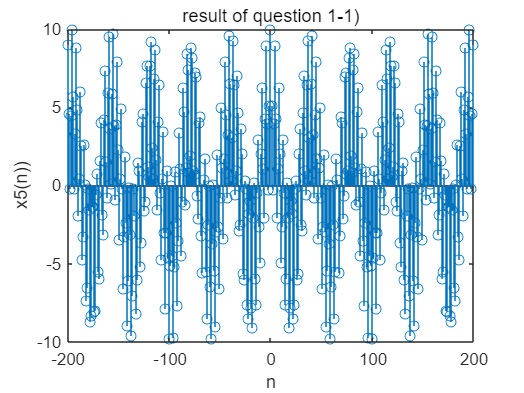

n=(-200:200);
x=5*cos(0.49*pi*n)+5*cos(0.051*pi*n);
Hs=stem(n,x);
title('result of question 1-1)')
xlabel('n'); ylabel('x5(n))');

2) 

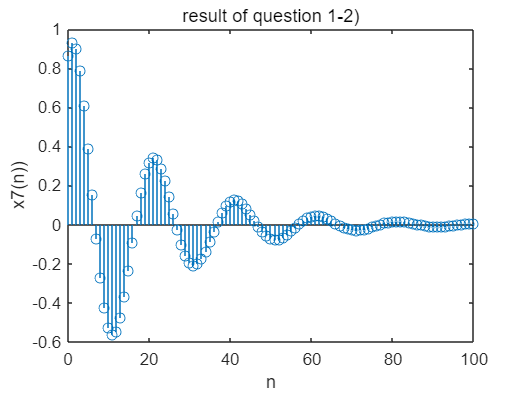

n=(0:100);
x = exp(-0.05*n).*sin(0.1*pi*n+pi/3); 
secondquestion=stem(n,x);
title('result of question 1-2)')
xlabel('n'); ylabel('x7(n))');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

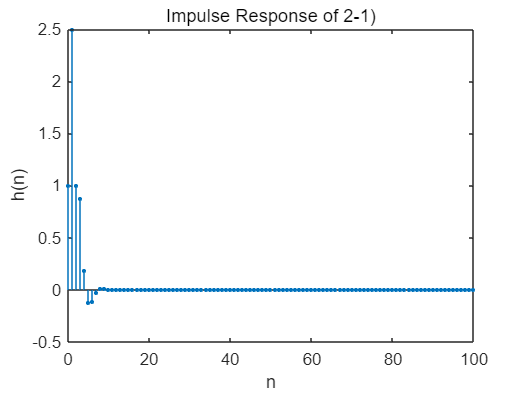

b=[1,2,0,1]; a=[1, -0.5, 0.25]; n=(0:100);
 h=impz(b,a,n);
 tt=stem(n,h,'filled');
 title('Impulse Response of 2-1)'); xlabel('n'); ylabel('h(n)');
 set(tt,'markersize',2);

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))

ans = 5.8571

3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

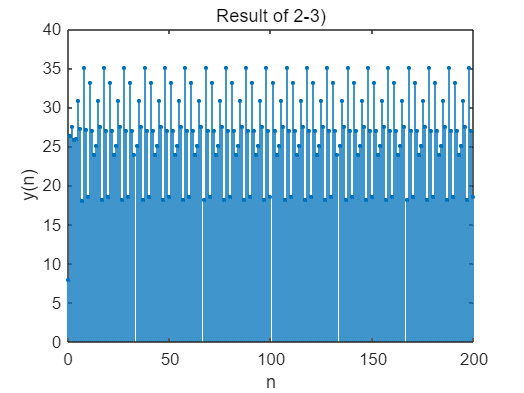

b=[1, 2, 0, 1]; a=[1, -0.5, 0.25]; n=(0:200);
x=5*ones(size(n))+3*cos(0.8*pi*n)+4*sin(0.6*pi*n);
y=filter(b,a,x);

oo=stem(n,y,'filled');
title('Result of 2-3)'); xlabel('n'); ylabel('y(n)');
set(oo,'markersize',2);   

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

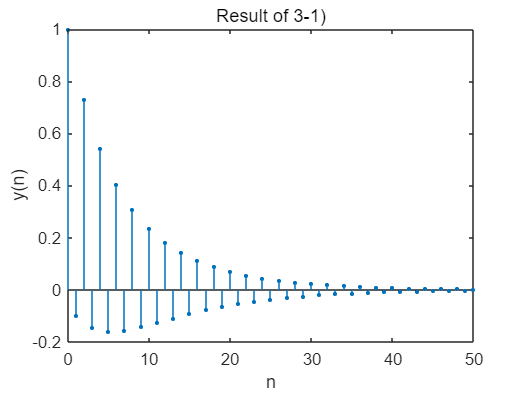

n=(0:50);

y=((0.8).^(n+1)-(-0.9).^(n+1))/(0.8+0.9);


resulty= stem(n,y,'filled');
title('Result of 3-1)'); xlabel('n'); ylabel('y(n)');

set(resulty,'markersize',2);

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

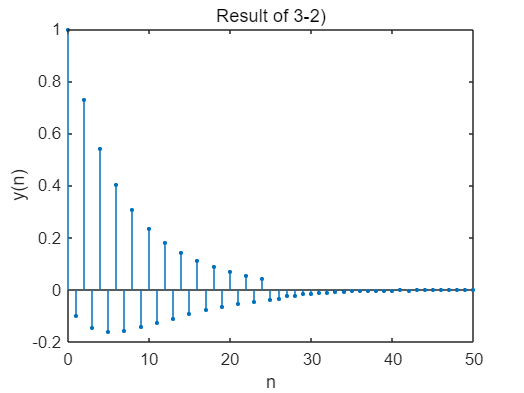

x=0.8.^n;
h=(-0.9).^n;

x1 = x(1:26);
h1 = h(1:26);
y1 = conv(h1,x1);


cvr = stem(n,y1,'filled');
title('Result of 3-2)'); xlabel('n'); ylabel('y(n)');

set(cvr,'markersize',2);

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

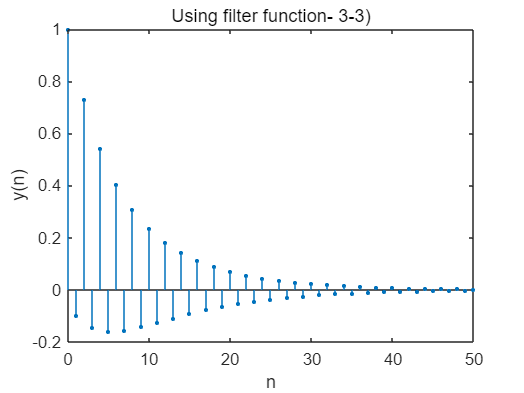

y2= filter((1),[1,0.9],x);

resulty2= stem(n,y2,'filled');
title('Using filter function- 3-3)'); xlabel('n'); ylabel('y(n)');

set(resulty2,'markersize',2);

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

w=(-300:300)*pi/300;
H=(0.19)*ones(size(w))./(1.81-1.8*cos(w));
magH=abs(H); angH=angle(H)*180/pi;

subplot(2,2,1); plot(w/pi,magH); grid;
title('Magnitude Response of 4-1)'); xlabel('frequency in pi units'); ylabel('|H|');
subplot(2,2,2); plot(w/pi,angH); grid;
title('Phase Response of 4-1)'); xlabel('frequency in pi units'); ylabel('Phase in pi Radians');


2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

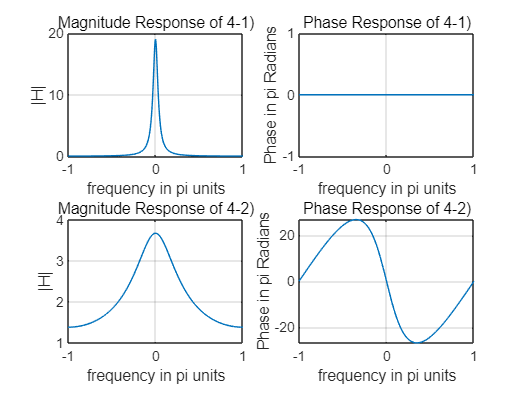

w=(-300:300)*pi/300;
H=(2-0.9*exp(-1j*w))./(1-0.9*exp(-1j*w)+0.2*exp(-1j*2*w));
magH=abs(H); angH=angle(H)*180/pi;

subplot(2,2,3); plot(w/pi,magH); grid;
title('Magnitude Response of 4-2)'); xlabel('frequency in pi units'); ylabel('|H|');
subplot(2,2,4); plot(w/pi,angH); grid;
title('Phase Response of 4-2)'); xlabel('frequency in pi units'); ylabel('Phase in pi Radians');

5. (P3.17) 

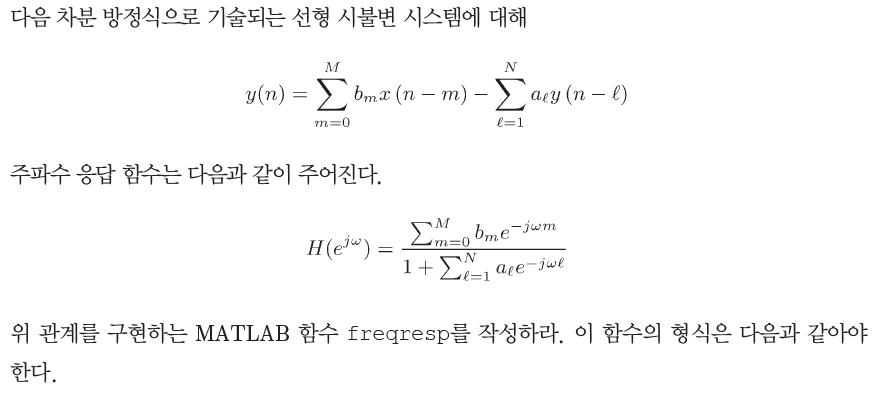

% function은 문제6 아래에 작성하였습니다

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

 w=(-300:300)*pi/300;
 a=[1,-0.95,0.9025]; b = [1, 0,-1];

[H]=freqresp(b,a,w);
magH = abs(H); phaH = angle(H)*180/pi;
 
 subplot(2,2,1); plot(w/pi,magH); grid; 
 title('Magnitude Response of 6-1)'); xlabel('frequency in pi units'); ylabel('|H|');
 subplot(2,2,2); plot(w/pi,phaH); grid;
 title('Phase Response of 6-1)'); xlabel('frequency in pi units'); ylabel('Phase in pi Radians');


2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

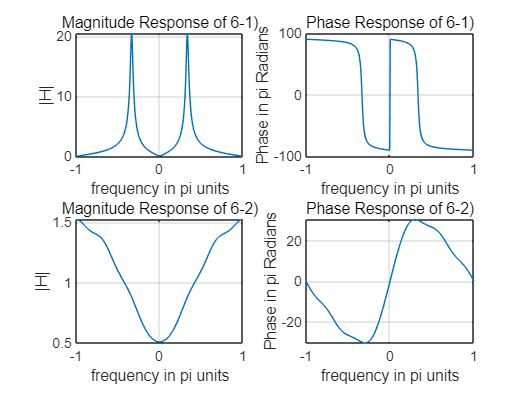

w=(-300:300)*pi/300; l=(0:5);
a=0.5.^l;
b=(1);


[H]=freqresp(b,a,w);
magH = abs(H); phaH = angle(H)*180/pi;

subplot(2,2,3); plot(w/pi,magH);  grid;  
title('Magnitude Response of 6-2)'); xlabel('frequency in pi units'); ylabel('|H|');
subplot(2,2,4); plot(w/pi,phaH); grid;
title('Phase Response of 6-2)'); xlabel('frequency in pi units'); ylabel('Phase in pi Radians');

function [H] = freqresp(b,a,w)

b=reshape(b,1,length(b));
a=reshape(a,1,length(a));
w=reshape(w,1,length(w));

m=0:length(b)-1;
ft1= b*exp(-1j*m'*w);
l=0:length(a)-1;
ft2=a*exp(-1j*l'*w);

H = ft1./ft2;

end
